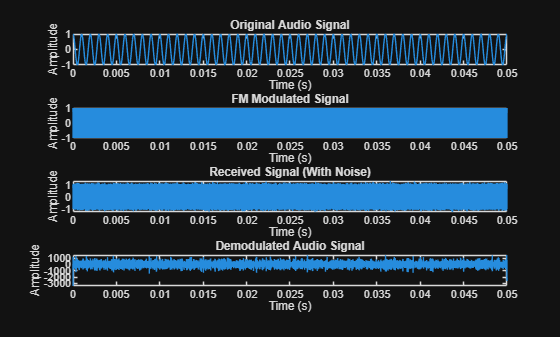

clc
clear
close all

%% PARAMETERS
fs = 200e3;          % Sampling frequency (200 kHz)
t = 0:1/fs:0.05;     % Time vector

fc = 50e3;           % Carrier frequency (50 kHz)
fm = 1e3;            % Modulating frequency (1 kHz)
beta = 5;            % Modulation index

%% MODULATING SIGNAL (AUDIO)
m = cos(2*pi*fm*t);

%% FM MODULATION
s = fmmod(m, fc, fs, beta);

%% ADD CHANNEL NOISE (SIMULATING REAL RADIO CHANNEL)
snr = 20; 
r = awgn(s, snr, 'measured');

%% FM DEMODULATION
demod = fmdemod(r, fc, fs, beta);

%% FREQUENCY SPECTRUM ANALYSIS
n = length(t);
f = (-n/2:n/2-1)*(fs/n);

M = fftshift(abs(fft(m)));
S = fftshift(abs(fft(s)));
R = fftshift(abs(fft(demod)));

%% PLOTS

figure

subplot(4,1,1)
plot(t,m)
title('Original Audio Signal')
xlabel('Time (s)')
ylabel('Amplitude')

subplot(4,1,2)
plot(t,s)
title('FM Modulated Signal')
xlabel('Time (s)')
ylabel('Amplitude')

subplot(4,1,3)
plot(t,r)
title('Received Signal (With Noise)')
xlabel('Time (s)')
ylabel('Amplitude')

subplot(4,1,4)
plot(t,demod)
title('Demodulated Audio Signal')
xlabel('Time (s)')
ylabel('Amplitude')

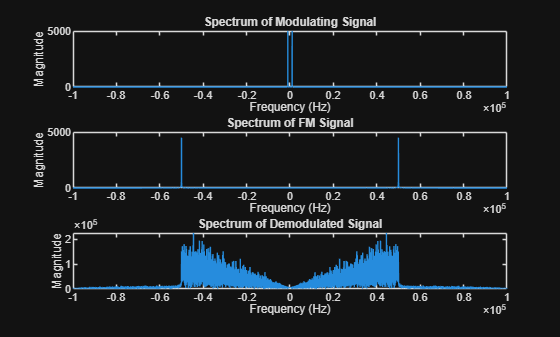


%% FREQUENCY DOMAIN

figure

subplot(3,1,1)
plot(f,M)
title('Spectrum of Modulating Signal')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

subplot(3,1,2)
plot(f,S)
title('Spectrum of FM Signal')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

subplot(3,1,3)
plot(f,R)
title('Spectrum of Demodulated Signal')
xlabel('Frequency (Hz)')
ylabel('Magnitude')